## Gerando sinal chirp

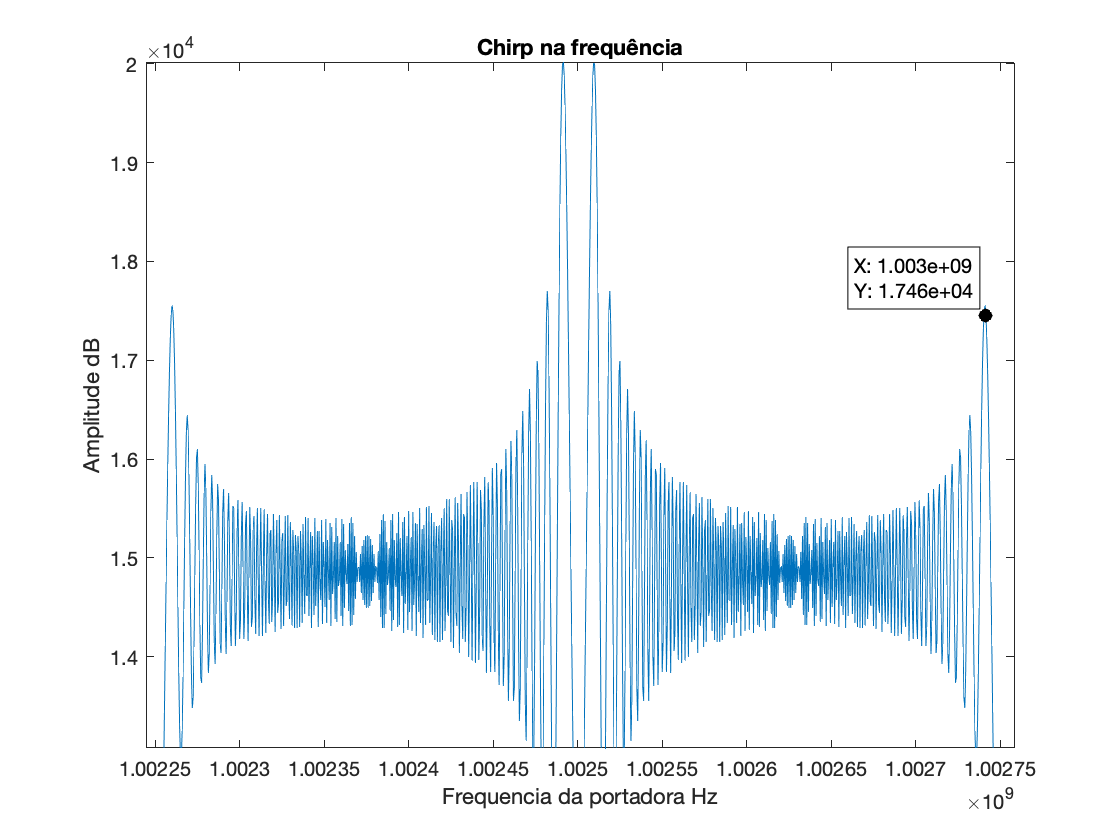

%% PARAMS

dPRF = 1700;    %Hz
dFreqInicial = 1e9; %GHz
dLarguraBanda = 5e6;%MHz;
dFreqAmostragem = 100e6; %MHz
dDuracaoPulso = 100e-6; %s
dTempoInicial = 0;

dFaseInicial = 0; %rad
dAmplitude = 1;
k=dLarguraBanda/dDuracaoPulso;


adTempo = [dTempoInicial:1/dFreqAmostragem:dDuracaoPulso];
uiNumAmostrasTempo = length(adTempo);

adSinal = meu_chirp(dAmplitude,adTempo,dFreqInicial,dFaseInicial,k)

adFreq = dFreqInicial:dLarguraBanda/(uiNumAmostrasTempo-1):dFreqInicial+dLarguraBanda;

figure(1)
plot(fftshift(adFreq),20*log2(10)*abs(fft(adSinal)))
title('Chirp na frequência')
xlabel('Frequencia da portadora Hz')
ylabel('Amplitude dB')


uiNumPRTs = 32;

adTempoTx = zeros(1,32*uiNumAmostrasTempo);










